clc; clear all; close all;
s = tf('s');
Gp=[0.1*exp(-0.3*s)/(s+4)  2/(s+9)
 0.3*exp(-0.6*s)/(s+2)   0.5/(s+5)]

Gp =
 
  From input 1 to output...
                      0.1
   1:  exp(-0.3*s) * -----
                     s + 4
 
                      0.3
   2:  exp(-0.6*s) * -----
                     s + 2
 
  From input 2 to output...
         2
   1:  -----
       s + 9
 
        0.5
   2:  -----
       s + 5
 
Continuous-time transfer function.
Model Properties



Ts = 0.6;

%0.4/Ts % <---- verifica Ts para que la division see entero

PNDz = c2d(Gp,Ts,'zoh')

PNDz =
 
  From input 1 to output...
                0.01747 z + 0.005262
   1:  z^(-1) * --------------------
                    z - 0.09072
 
                  0.1048
   2:  z^(-1) * ----------
                z - 0.3012
 
  From input 2 to output...
          0.2212
   1:  ------------
       z - 0.004517
 
         0.09502
   2:  -----------
       z - 0.04979
 
Sample time: 0.6 seconds
Discrete-time transfer function.


PNDz = absorbDelay(PNDz);
Gss = ss(PNDz)

Gss =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1   0.09072         0         0         0         0         0
   x2     0.125         0         0         0         0         0
   x3         0         0    0.3012         0         0         0
   x4         0         0       0.5         0         0         0
   x5         0         0         0         0  0.004517         0
   x6         0         0         0         0         0   0.04979
 
  B = 
         u1    u2
   x1  0.25     0
   x2     0     0
   x3   0.5     0
   x4     0     0
   x5     0   0.5
   x6     0  0.25
 
  C = 
            x1       x2       x3       x4       x5       x6
   y1  0.06988   0.1684        0        0   0.4424        0
   y2        0        0        0   0.4193        0   0.3801
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.6 seconds
Discrete-time state-space model.



A = Gss.A;
B = Gss.B;
C = Gss.C

C =     0.0699    0.1684         0         0    0.4424         0
         0         0         0    0.4193         0    0.3801


D = Gss.D

D =      0     0
     0     0




%% Comprobando si es observable nx = rank
Obser = rank(obsv(A,C))

Obser = 6

nx = size(A,1)

nx = 6

ny=size(C,1);

contr = rank(ctrb(A, B)) %%% para cualquier tamaño de matrices

contr = 5


Qy=1000;
Ru=1;
Q=C'*Qy*C;
R=D'*Qy*D+Ru;
N=C'*Qy*D;
K=dlqr(A,B,Q,R,N)

K =    -0.0149    0.0000    0.3898    0.0000   -0.0005   -0.0076
    0.1040   -0.0000    0.3071   -0.0000    0.0075    0.0312


nx=size(A,1);
Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;



G=eye(nx);
Qw=0.1*eye(nx);
Vv=0.0001*eye(ny);
L=dlqe(A,G,C,Qw,Vv);
ACL=[A -B*K;L*C A-B*K-L*C];
BCL=[B*Kr;B*Kr];
CCL=[C -D*K];
DCL=D*Kr;
GCL = minreal(ss(ACL,BCL,CCL,DCL,Ts));

7 states removed.


abs(pole(GCL))

ans =     0.0998
    0.0998
    0.0495
    0.0009
    0.0000


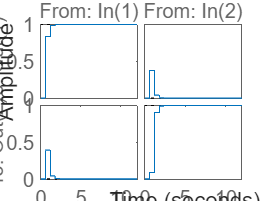

step(GCL)




% nx = size(A,1)
% ny = size(C,1)
% nu = size(B,2)
% 
% Qy=diag([1 1 1 1 1 1 1 1000]);
% Ru=1;
% QOL=C'*Qy*C;
% ROL=D'*Qy*D+Ru;
% N=C'*Qy*D;
% 
% AOL=[A zeros(nx,ny);-C zeros(ny,ny)]
% BOL=[B;zeros(ny,nu)]
% 
% % QOL=diag([1 1 1 1 1 1 1 1000])
% % ROL=0.001;
% KOL=lqr(AOL,BOL,QOL,ROL,N)
% K=KOL(:,1:nx)
% Ki=-KOL(:,(nx+1):end)
% 
% %2do paso LQG
% Qw=0.001;
% Vv=0.0001;
% L=lqe(A,G,C,Qw,Vv)
% ACL = [A - B*K, B*Ki;
%        L*C,A - B*K - L*C,B*Ki;
%       -C,D*K, eye(ny) - D*Ki];
% BCL=[zeros(nx,ny);
%     zeros(nx,ny);
%     eye(ny,ny)];
% 
% CCL = [C, -D*K, D*Ki];
% DCL=[zeros(ny,ny)];
GCL = minreal(ss(ACL,BCL,CCL,DCL,Ts));
abs(pole(GCL))
step(GCL)

